Alen Mehmedbegovic January 25th - Harris corner detection 

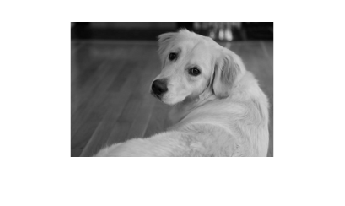

% We can match a feature of two images to each other and compare them 
% This is our main motivation behind feature matching, combining two
% similar images in a way 

% 1) Detection. This is what we will do today. We focus on specifying a
% location within the image. 
% Check google docs notes for theory notes 
image = rgb2gray(im2double(imresize(imread("sherlock.jpg"), 0.25)));
imshow(image)

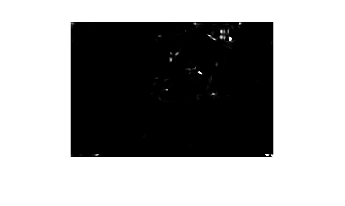


% Create second moment matrix
sobel = [-1 0 1; -2 0 2; -1 0 1];
gaus = fspecial('gaussian', 5 ,1);
dog = conv2(gaus, sobel); % Does denoising and gradient computation at same time 

ix = imfilter(image, dog);
iy = imfilter(image, dog'); % Gradients in x & y direction
ix2g = imfilter(ix.*ix, gaus);
iy2g = imfilter(iy.*iy, gaus);
ixiyg = imfilter(ix.*iy, gaus);

harcor = ix2g.*iy2g - ixiyg .* ixiyg - 0.05*(ix2g + iy2g).^2;
imshow(harcor * 50);

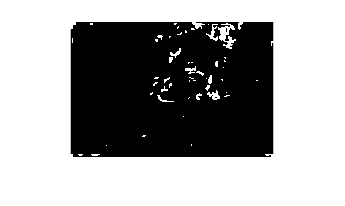

% We can see the strongest edges, with the blacks being small negative
% values. Meaning we need a small but positive threshold 
corners = harcor > 0.0002;
imshow(corners)

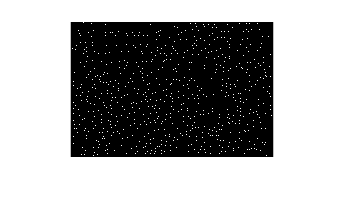


% This looks at neighbourhood and puts 1 at local max for every pixel,
% If local max = pixel value, we know its local max 
localmax = imdilate(harcor, ones(3));
imshow(harcor == localmax)

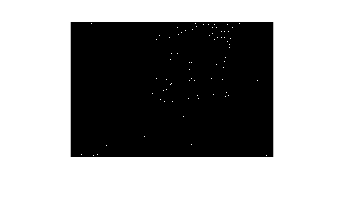

imshow((harcor == localmax).*(corners)) % These are harris corners 

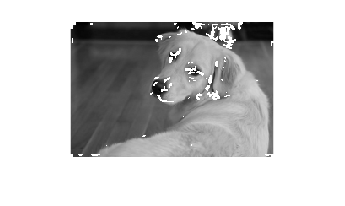


corvis = image;
corvis(corners > 0) = 1;
imshow(corvis);